## **CYKLY PŘEPLŇOVANÝCH SPALOVACÍCH MOTORŮ**

 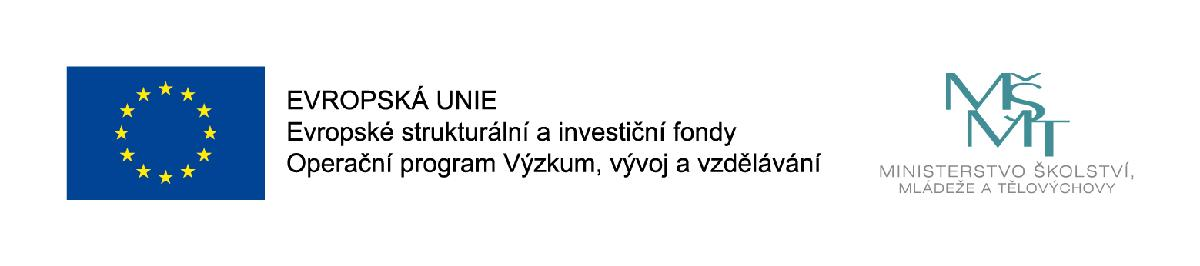

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

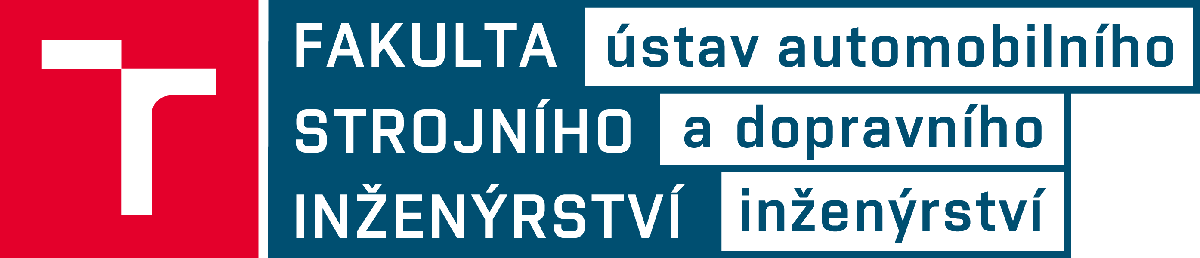

**ZVYŠOVÁNÍ VÝKONU MOTORŮ **dosáhneme, když **zvýšíme**:

- zdvihový objem - vede na zvětšení rozměrů motoru

- otáčky -  technicky náročné

- zlepšíme plnění válců (přeplňování) - technicky nejvýhodnější 

**Přeplňováním zajistíme:**

- zvýšení výkonu motoru a točivého momentu

- zvýšení účinnosti motoru 

- snížení měrné spotřeby paliva

- snížení emisí škodlivin 

**SKUPINY PŘEPLŇOVÁNÍ**

**Nízkotlaké**  **0,12 ****– 0,15 ****MPa**

                             - zvýšení výkonu o 50 %

                          - stlačený vzduch se nechladí

**Středotlaké**    **0,15 ****– 0,18 ****MPa**

                           - zvýšení výkonu o 50 - 70 %

                           - většinou se používá mezichladič   stlačeného vzduchu

**Vysokotlaké **   **0,18 ****MPa**** i více**

                             - zvýšení výkonu o 75 %  i více

                             - vždy se používá mezichladič

                               stlačeného vzduchu

**MECHANICKY POHÁNĚNÁ DMYCHADLA (KOMPRESORY)**

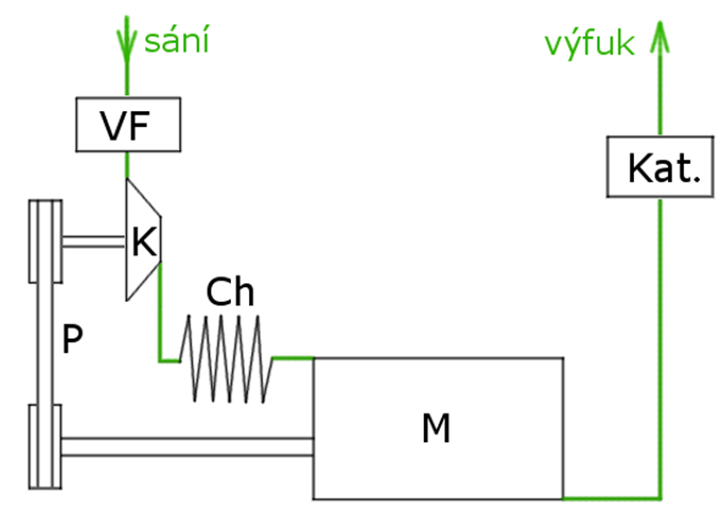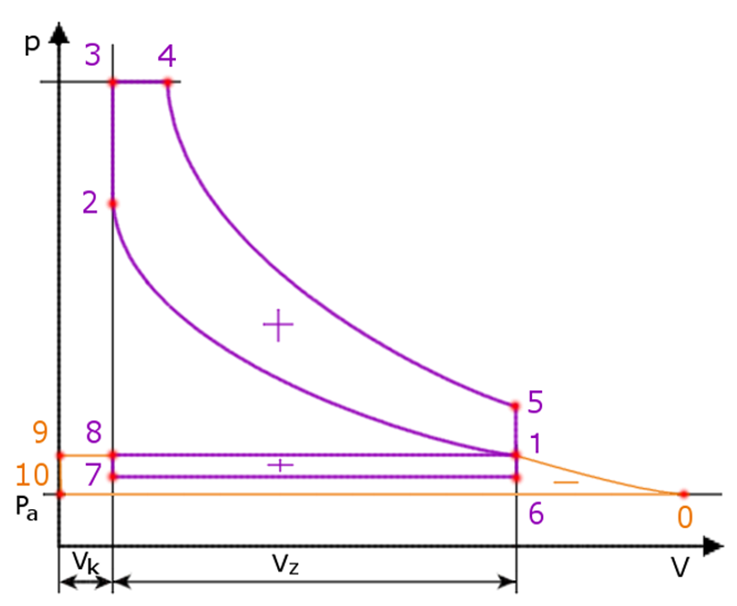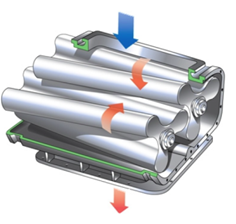

**TURBODMYCHADLO S ROVNOTLAKÝM PROVOZEM TURBÍNY **- poháněna výfukovými plyny

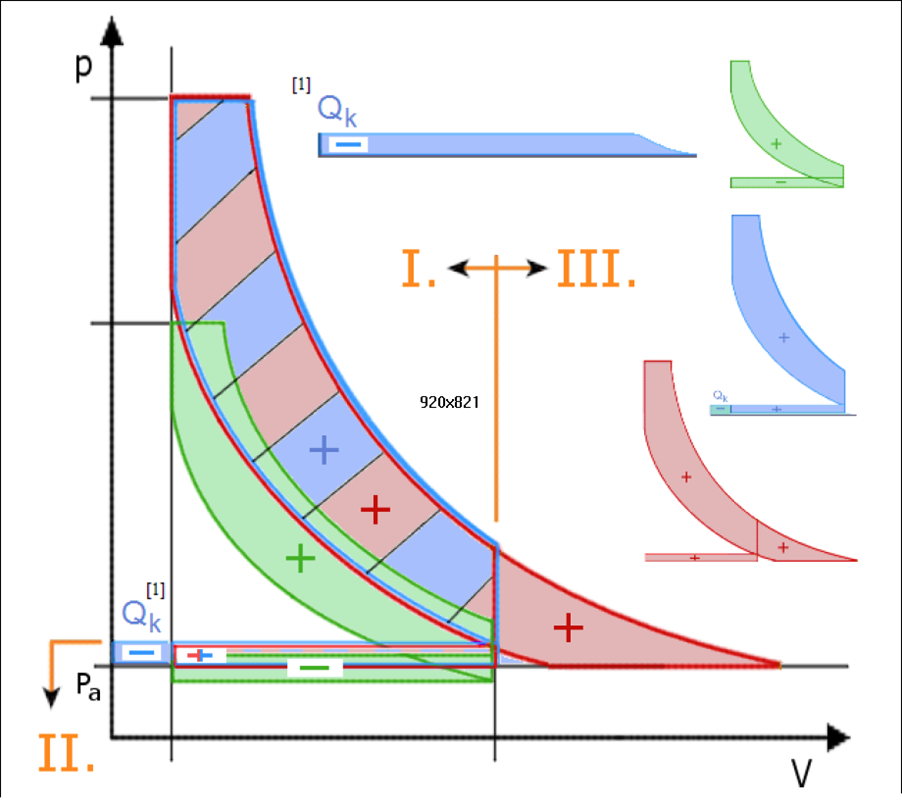

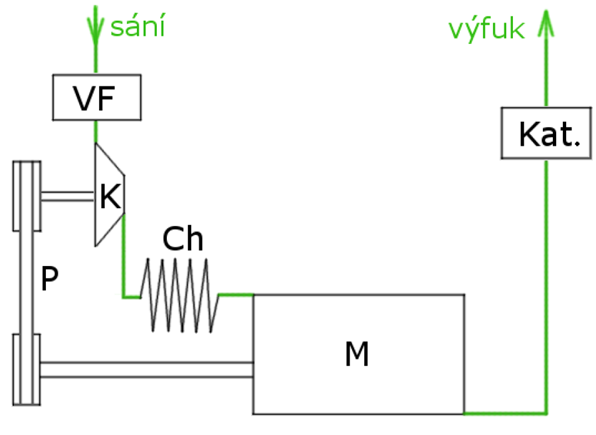

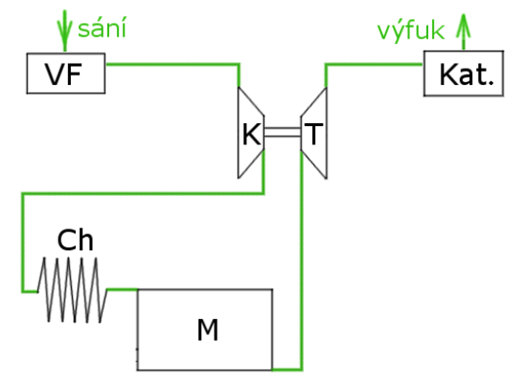

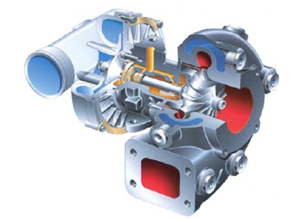

### Příklad nepřeplňovaný motor

Pracovní látkou zážehového čtyřdobého motoru je ideálním plyn s plynovou konstantou 289,7 J/kgK, který uvažujeme jako tříatomový. Měrná tepla uvažujte konstantní. Čtyřválcový motor má vrtání motoru je 82,5 mm a zdvih 92,8 mm. Tlak nasávaného vzduchu je 1000 hPa a teplota 24 °C a kompresní poměr 10,5.

Určete stavové veličiny v charakteristických bodech cyklu, přivedené teplo, odvedené teplo, práci cyklu a termickou účinnost, střední teoretický tlak, Stanovete maximální výkon při otáčkách maximálního výkonu jsou 5700 1/min. Nakreslete p-v a T-s diagram.

clear all;
Vrtani = 82.5;     % [mm] vrtání válce
Zdvih  = 92.8;     % [mm] Zdvih válce
ivalcu = 4;        %      Počet válců     
p1hPa = 1000;      % [hPa] tlak nasávaného vzduchu
t1C   = 24;        % [°C]  teplota nasávaného vzduchu
eps   = 10.5;      % [-]  kompresní poměr
notacky = 5700.0;  % [1/min] otáčky motoru
r = 289.7;         % [J/kgK] plynová konstanta
kappa = 1.3;       % 
Hu = 42.0;         % [MJ/kg] Výhřevnost
lambda = 0.98;     % [-] Součinitel přebytku vzduchu
Saf = 14.7;        % [-]
etach = 0.85;      % [-] Účinnost přeměny

Rozměry motoru

Vzl = pi * mm2dm(Vrtani) * mm2dm(Vrtani) * mm2dm(Zdvih) / 4.0

Vzl = 0.4961

Vkl = Vzl/(eps-1);
V1l = Vzl + Vkl;
Vzml = Vzl * ivalcu;
fprintf('Zdvihový objem motoru : %.3f [l]\n',Vzml);

Zdvihový objem motoru : 1.984 [l]


Výpočet vlastností plynu

cv = 1/(kappa-1) * r;
cp = cv * kappa;

Bod 1

T1 = C2K(t1C);
p1 = hPa2Pa(p1hPa);
V1 = l2m3(V1l);
m1 = p1*V1/(r*T1); 
mf = m1 / (1+lambda * Saf);
Qh = MJ2J(Hu) * mf * etach;

Bod 2

V2 = V1/eps;
p2 = p1 * eps^kappa;
T2 = p2*V2/(r*m1);

Bod 3

T3 = Qh/(m1 * cv) + T2;
p3 = p2*T3/T2;
V3 = m1*r*T3/p3;

Bod 4

p4 = p3 *(V3/V1)^kappa;
V4 = V1;
T4 = T1*(p4/p1);

## Data pro kreslení grafů

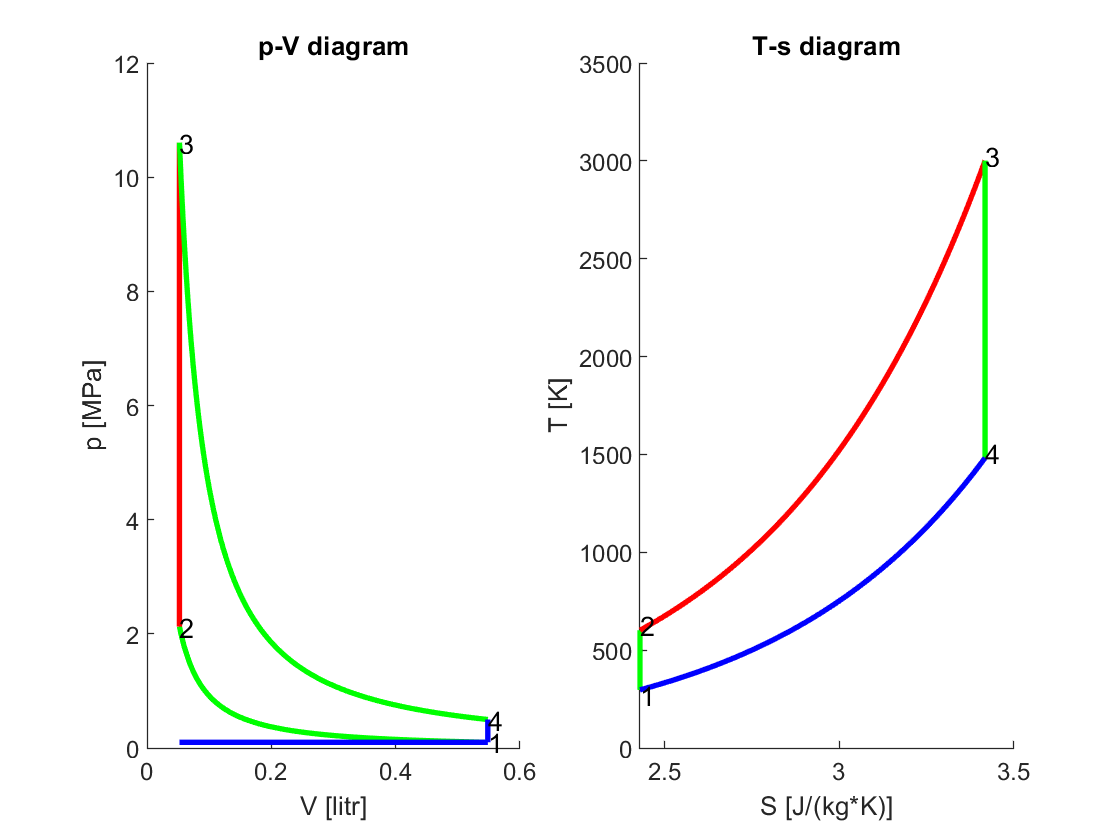

Vv1 = linspace(V1,V2,180);
pv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);
for i=2:180
  pv1(i) = p1*V1^kappa/Vv1(i)^kappa;
  Tv1(i) = pv1(i) * Vv1(i) / (r * m1);
  Sv1(i)=m1*cp*log(Tv1(i))-m1*r*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
Vv1(1) = V1;
Vv1(180) = V2;
Tv1(1) = pv1(1) * Vv1(1) / (r * m1);
Sv1(1)=m1*cp*log(Tv1(1))-m1*r*log(pv1(1));

pv2 = linspace(p2,p3,180);
Vv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  Vv2(i)= V2;
  Tv2(i) = pv2(i) * Vv2(i) / (r * m1);
  Sv2(i)=m1*cp*log(Tv2(i))-m1*r*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
Vv2(1) = V2;
Vv2(180) = V3;
Tv2(1) = pv2(1) * Vv2(1) / (r * m1);
Sv2(1)=m1*cp*log(Tv2(1))-m1*r*log(pv2(1));

Vv3 = linspace(V3,V4,180);
pv3 = zeros([1,180]);
for i=2:180
  pv3(i)=p3*V3^kappa/Vv3(i)^kappa;
  Tv3(i) = pv3(i) * Vv3(i) / (r * m1);
  Sv3(i)=m1*cp*log(Tv3(i))-m1*r*log(pv3(i));    
end
pv3(1) = p3;
pv3(180) = p4;
Vv3(1) = V3;
Vv3(180) = V4;
Tv3(1) = pv3(1) * Vv3(1) / (r * m1);
Sv3(1)=m1*cp*log(Tv3(1))-m1*r*log(pv3(1));    

pv4 = linspace(p4,p1,180);
Vv4 = zeros([1,180]);
Tv4 = zeros([1,180]);
Sv4 = zeros([1,180]);
for i=2:180
  Vv4(i)= V4;
  Tv4(i) = pv4(i) * Vv4(i) / (r * m1);
  Sv4(i)=m1*cp*log(Tv4(i))-m1*r*log(pv4(i));
end
pv4(1) = p4;
pv4(180) = p1;
Vv4(1) = V4;
Vv4(180) = V1;
Tv4(1) = pv4(1) * Vv4(1) / (r * m1);
Sv4(1)=m1*cp*log(Tv4(1))-m1*r*log(pv4(1));

Vv0 = linspace(V1,V2,180);
pv0 = zeros([1,180]);
for i=2:180
  pv0(i)= p1;
end
pv0(1) = p1;
pv0(180) = p1;
Vv0(1) = V1;
Vv0(180) = V2;

% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vv1*10^3,pv1/10^6,'g-','linewidth',2);
plot(Vv2*10^3,pv2/10^6,'r-','linewidth',2);
plot(Vv3*10^3,pv3/10^6,'g-','linewidth',2);
plot(Vv4*10^3,pv4/10^6,'b-','linewidth',2);
plot(Vv0*10^3,pv0/10^6,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Vv1(1)*10^3,(pv1(1)-0.2)/10^6,'1');
text(Vv2(1)*10^3,(pv2(1)-0.2)/10^6,'2');
text(Vv3(1)*10^3,(pv3(1)+0.2)/10^6,'3');
text(Vv4(1)*10^3,(pv4(1)+0.2)/10^6,'4');
% název grafu a popisy os
title('p-V diagram')
xlabel('V [litr]')
ylabel('p [MPa]')                     
subplot(1,2,2);
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'g-','linewidth',2);
plot(Sv4,Tv4,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
% název grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]')                      % ^\circC

###  Tepla a práce

%Qh = m1 * cp * (T3-T2);
Qc = m1 * cv * (T1-T4);
Ao = Qh - abs(Qc);
% Výkon čtyřdobého motoru
Pt = Ao * notacky/60.0/2.0 * ivalcu;
% Termická účinnost
etat = Ao / Qh;
% výstupní data
clc;
fprintf('p1 : %.1f kPa V1 : %.1f ccm T1 :  %.1f K \n',Pa2kPa(p1), V1*1000000.0, T1);

p1 : 100.0 kPa V1 : 548.3 ccm T1 :  297.1 K 


fprintf('p2 : %.1f kPa V2 : %.1f ccm T2 :  %.1f K \n',Pa2kPa(p2), V2*1000000.0, T2);

p2 : 2125.9 kPa V2 : 52.2 ccm T2 :  601.6 K 


fprintf('p3 : %.1f kPa V3 : %.1f ccm T3 :  %.1f K \n',Pa2kPa(p3), V3*1000000.0, T3);

p3 : 10605.3 kPa V3 : 52.2 ccm T3 :  3001.3 K 


fprintf('p4 : %.1f kPa V4 : %.1f ccm T4 :  %.1f K \n',Pa2kPa(p4), V4*1000000.0, T4);

p4 : 498.9 kPa V4 : 548.3 ccm T4 :  1482.4 K 


fprintf('Přivedené teplo  : %.1f [J]\n',Qh);

Přivedené teplo  : 1475.9 [J]


fprintf('Odvedené teplo   : %.1f [J]\n',Qc);

Odvedené teplo   : -729.0 [J]


fprintf('Práce cyklu      : %.1f [J]\n',Ao);

Práce cyklu      : 747.0 [J]


fprintf('Výkon motoru     : %.1f [kW]\n',W2kW(Pt));

Výkon motoru     : 141.9 [kW]


fprintf('Termická účinnost: %.3f\n',etat);

Termická účinnost: 0.506


### Příklad přeplňovaný motor mechanicky poháněným kompresorem

Pracovní látkou zážehového čtyřdobého motoru je ideálním plyn s plynovou konstantou 289,7 J/kgK, který uvažujeme jako tříatomový. Měrná tepla uvažujte konstantní. Čtyřválcový motor má vrtání motoru je 82,5 mm a zdvih 92,8 mm. Tlak nasávaného vzduchu je 1000 hPa a teplota 24 °C a kompresní poměr 10,5. Maximální teplota cyklu je 2700 °C. 

Určete stavové veličiny v charakteristických bodech cyklu, přivedené teplo, odvedené teplo, práci cyklu a termickou účinnost, střední teoretický tlak, Stanovete maximální výkon při otáčkách maximálního výkonu jsou 5700 1/min. Nakreslete p-v a T-s diagram.

clear all;
Vrtani = 82.5;     % [mm] vrtání válce
Zdvih  = 92.8;     % [mm] Zdvih válce
ivalcu = 4;        %      Počet válců     
p1hPa = 1000;      % [hPa] tlak nasávaného vzduchu
t1C   = 24;        % [°C]  teplota nasávaného vzduchu
eps   = 10.5;      % [-]  kompresní poměr
notacky = 5700.0;  % [1/min] otáčky motoru
r = 289.7;         % [J/kgK] plynová konstanta
kappa = 1.3;       % 
Hu = 42.0;         % [MJ/kg] Výhřevnost
lambda = 0.98;     % [-] Součinitel přebytku vzduchu
Saf = 14.7;        % [-]
etach = 0.85;      % [-] Účinnost přeměny
plnici = 90.0;     % [kPa] Plnící přetlak
tplniciC = 70.0    % [°C] Plnicí teplota za chladičem vzduchu

tplniciC = 70

rair = 287.1;      % [J/kgK] plynová konstanta vzduchu
kappaair = 1.41;   % [] Poissonova konstanta vzduchu

Rozměry motoru

Vzl = pi * mm2dm(Vrtani) * mm2dm(Vrtani) * mm2dm(Zdvih) / 4.0

Vzl = 0.4961

Vkl = Vzl/(eps-1);
V1l = Vzl + Vkl;
Vzml = Vzl * ivalcu;
fprintf('Zdvihový objem motoru : %.3f [l]\n',Vzml);

Zdvihový objem motoru : 1.984 [l]


Výpočet vlastností plynu

cv = 1/(kappa-1) * r;
cp = cv * kappa;

Bod 1

T1 = C2K(tplniciC);
p1 = hPa2Pa(p1hPa)+kPa2Pa(plnici);
V1 = l2m3(V1l);
m1 = p1*V1/(r*T1); 
mf = m1 / (1+lambda * Saf);
Qh = MJ2J(Hu) * mf * etach;

Bod 2

V2 = V1/eps;
p2 = p1 * eps^kappa;
T2 = p2*V2/(r*m1);

Bod 3

T3 = Qh/(m1 * cv) + T2;
p3 = p2*T3/T2;
V3 = m1*r*T3/p3;

Bod 4

p4 = p3 *(V3/V1)^kappa;
V4 = V1;
T4 = p4 * V4 / (m1 * r);

Bod 5

p5 = hPa2Pa(p1hPa);
V5 = V1;
T5 = p5 * V5 / (m1 * r);

## Data pro kreslení grafů

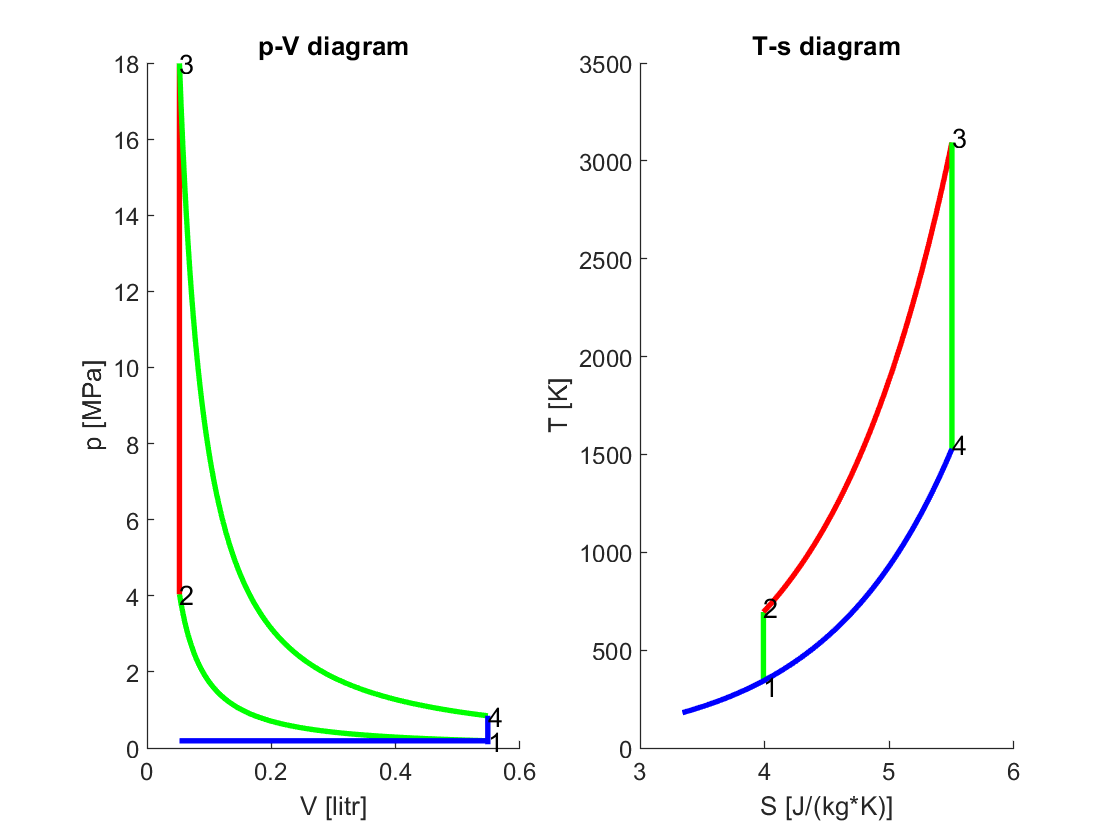

Vv1 = linspace(V1,V2,180);
pv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);
for i=2:180
  pv1(i) = p1*V1^kappa/Vv1(i)^kappa;
  Tv1(i) = pv1(i) * Vv1(i) / (r * m1);
  Sv1(i)=m1*cp*log(Tv1(i))-m1*r*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
Vv1(1) = V1;
Vv1(180) = V2;
Tv1(1) = pv1(1) * Vv1(1) / (r * m1);
Sv1(1)=m1*cp*log(Tv1(1))-m1*r*log(pv1(1));
%-----------------
pv2 = linspace(p2,p3,180);
Vv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  Vv2(i)= V2;
  Tv2(i) = pv2(i) * Vv2(i) / (r * m1);
  Sv2(i)=m1*cp*log(Tv2(i))-m1*r*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
Vv2(1) = V2;
Vv2(180) = V3;
Tv2(1) = pv2(1) * Vv2(1) / (r * m1);
Sv2(1)=m1*cp*log(Tv2(1))-m1*r*log(pv2(1));
%--------------------
Vv3 = linspace(V3,V4,180);
pv3 = zeros([1,180]);
for i=2:180
  pv3(i)=p3*V3^kappa/Vv3(i)^kappa;
  Tv3(i) = pv3(i) * Vv3(i) / (r * m1);
  Sv3(i)=m1*cp*log(Tv3(i))-m1*r*log(pv3(i));    
end
pv3(1) = p3;
pv3(180) = p4;
Vv3(1) = V3;
Vv3(180) = V4;
Tv3(1) = pv3(1) * Vv3(1) / (r * m1);
Sv3(1)=m1*cp*log(Tv3(1))-m1*r*log(pv3(1));    
%-------------------------
pv4 = linspace(p4,p5,180);
Vv4 = zeros([1,180]);
Tv4 = zeros([1,180]);
Sv4 = zeros([1,180]);
for i=2:180
  Vv4(i)= V4;
  Tv4(i) = pv4(i) * Vv4(i) / (r * m1);
  Sv4(i)=m1*cp*log(Tv4(i))-m1*r*log(pv4(i));
end
pv4(1) = p4;
pv4(180) = p5;
Vv4(1) = V4;
Vv4(180) = V1;
Tv4(1) = pv4(1) * Vv4(1) / (r * m1);
Sv4(1)=m1*cp*log(Tv4(1))-m1*r*log(pv4(1));
%------Sací tlak
Vv0 = linspace(V1,V2,180);
pv0 = zeros([1,180]);
for i=2:180
  pv0(i)= p1;
end
pv0(1) = p1;
pv0(180) = p1;
Vv0(1) = V1;
Vv0(180) = V2;

% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vv1*10^3,pv1/10^6,'g-','linewidth',2);
plot(Vv2*10^3,pv2/10^6,'r-','linewidth',2);
plot(Vv3*10^3,pv3/10^6,'g-','linewidth',2);
plot(Vv4*10^3,pv4/10^6,'b-','linewidth',2);
plot(Vv0*10^3,pv0/10^6,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Vv1(1)*10^3,(pv1(1)-0.2)/10^6,'1');
text(Vv2(1)*10^3,(pv2(1)-0.2)/10^6,'2');
text(Vv3(1)*10^3,(pv3(1)+0.2)/10^6,'3');
text(Vv4(1)*10^3,(pv4(1)+0.2)/10^6,'4');
% název grafu a popisy os
title('p-V diagram')
xlabel('V [litr]')
ylabel('p [MPa]')                     
subplot(1,2,2);
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'g-','linewidth',2);
plot(Sv4,Tv4,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
% název grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]')                      % ^\circC

###  Tepla a práce

%Qh = m1 * cp * (T3-T2);
Qc = m1 * cv * (T1-T4);
Ao = Qh - abs(Qc);
% Výkon čtyřdobého motoru
Pt = Ao * notacky/60.0/2.0 * ivalcu;
% Termická účinnost
etat = Ao / Qh;
% výstupní data
clc;
fprintf('p1 : %.1f kPa V1 : %.1f ccm T1 :  %.1f K \n',Pa2kPa(p1), V1*1000000.0, T1);

p1 : 190.0 kPa V1 : 548.3 ccm T1 :  343.1 K 


fprintf('p2 : %.1f kPa V2 : %.1f ccm T2 :  %.1f K \n',Pa2kPa(p2), V2*1000000.0, T2);

p2 : 4039.2 kPa V2 : 52.2 ccm T2 :  694.8 K 


fprintf('p3 : %.1f kPa V3 : %.1f ccm T3 :  %.1f K \n',Pa2kPa(p3), V3*1000000.0, T3);

p3 : 17990.4 kPa V3 : 52.2 ccm T3 :  3094.4 K 


fprintf('p4 : %.1f kPa V4 : %.1f ccm T4 :  %.1f K \n',Pa2kPa(p4), V4*1000000.0, T4);

p4 : 846.2 kPa V4 : 548.3 ccm T4 :  1528.4 K 


fprintf('Přivedené teplo  : %.1f [J]\n',Qh);

Přivedené teplo  : 2428.3 [J]


fprintf('Odvedené teplo   : %.1f [J]\n',Qc);

Odvedené teplo   : -1199.4 [J]


fprintf('Práce cyklu      : %.1f [J]\n',Ao);

Práce cyklu      : 1229.0 [J]


fprintf('Výkon motoru     : %.1f [kW]\n',W2kW(Pt));

Výkon motoru     : 233.5 [kW]


fprintf('Termická účinnost: %.3f\n',etat);

Termická účinnost: 0.506


### Lokální funkce 

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [J] = MJ2J(MJ)
J = MJ*1000000.0;
end

Převod

function [Pa] = kPa2Pa(kPa)
Pa = kPa*1000.0;
end

Převod

function [dm] = mm2dm(mm)
dm = mm*0.01;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end